clear

#### Automatically find the port the Arduino is connected to

allPorts = serialportlist;  % list of all available ports
pat = "/dev/cu.usbmodem";   % text to look for

% logical array of matching ports
matchingPorts = startsWith(allPorts, pat);   

if any(matchingPorts)                   % If any matches were found,              
    numMatches = sum(matchingPorts);    % Count the number of matches.
    if size(numMatches) > 1             % If multiple matching ports were found, 
        error("Multiple ports found")   % throw an error.
    else                                % If only one match was found,
        port = allPorts(matchingPorts); % that string is the arduino port.
    end
else                                    % If no ports were found,
    error("Port not found")             % throw an error.
end


## Run Experiment 1 (forward velocity)

#### Create a serialport object to talk to the Arduino for the first experiment

for j=1:50

ard = serialport(port, 115200);   % creates a device object (port, baud)
configureTerminator(ard, "CR/LF") % sets the terminator

#### Wait for the Arduino

When the Arduino is ready, it sends "Start!"

readline(ard);

#### Tell the Arduino to start the forward velocity experiment (#1)

% disp('Starting forward velocity experiment in Arduino');
writeline(ard,"1"); % sends the start command to the Arduino

Read data from Arduino

k = 0; % array index
% stringArray = zeros(1001,5); % preallocate

% Read the first line of output from the Arduino
newData = readline(ard);
% Read new data until the Arduino signals it's done
while (~strncmp(newData,'Finished1',9)) 
    k = k + 1; % k++

    % save the line of text to stringArray(k)
    stringArray(k,:) = split(newData)';

    % Read a new line of data from Arduino
    newData = readline(ard);
end
clear newData ard; % Disconect from the Arduino

% change string data to cell array using tab delimiter 
dataArray = str2double(stringArray);

% Make time start at 0 and convert from ms to s
dataArray(:,1) = (dataArray(:,1))/1000;

% Save experiment 1 data to the exp1 data table
exp1 = array2table(dataArray,"VariableNames",{'time', 'posL', 'posR', 'sum','tL','tR','currentL','currentR'});

clear dataArray stringArray newData

WHEEL_RADIUS = 2.935;              % Radius of wheel in inches
WHEELBASE = 13.625;

minL(j) = min(exp1.tL(exp1.posL > 10));
minR(j) = min(exp1.tL(exp1.posR > 10));
minLsum(j) = min(exp1.sum(exp1.posL > 10));
minRsum(j) = min(exp1.sum(exp1.posR > 10));

fprintf('Trial %d Minimum Sum: %f\n', j, min(minRsum(j),minLsum(j)) )
% disp(j)
% figure
% plot(exp1.sum,exp1.posL,exp1.sum,exp1.posR);
% title("Minimum Voltage Commands " + string(j));
% ylabel('Position (counts)');
% xlabel('Command Sum');
% ylim([0,100]);
% grid on;
% % xline(minLsum(j),'Label','MinLsum','Color','b');
% % xline(minRsum(j),'Label','MinRsum','Color','r');
% legend('Left','Right')

clear exp1
end

Trial 1 Minimum Sum: 80.240100
Trial 2 Minimum Sum: 80.190000
Trial 3 Minimum Sum: 80.180000
Trial 4 Minimum Sum: 80.200000
Trial 5 Minimum Sum: 80.180000
Trial 6 Minimum Sum: 80.190000
Trial 7 Minimum Sum: 80.190000
Trial 8 Minimum Sum: 80.170000
Trial 9 Minimum Sum: 80.170000
Trial 10 Minimum Sum: 80.310100
Trial 11 Minimum Sum: 80.340100
Trial 12 Minimum Sum: 80.320100
Trial 13 Minimum Sum: 80.330100
Trial 14 Minimum Sum: 80.350100
Trial 15 Minimum Sum: 88.461800
Trial 16 Minimum Sum: 80.190000
Trial 17 Minimum Sum: 80.640100
Trial 18 Minimum Sum: 80.190000
Trial 19 Minimum Sum: 95.003200
Trial 20 Minimum Sum: 80.410100
Trial 21 Minimum Sum: 80.290100
Trial 22 Minimum Sum: 80.360100
Trial 23 Minimum Sum: 80.590100
Trial 24 Minimum Sum: 80.230100
Trial 25 Minimum Sum: 80.220100
Trial 26 Minimum Sum: 80.310100
Trial 27 Minimum Sum: 80.260100
Trial 28 Minimum Sum: 80.290100
Trial 29 Minimum Sum: 80.310100
Trial 30 Minimum Sum: 80.330100
Trial 31 Minimum Sum: 80.190000
Trial 32 Minimum 

save minSpeed.mat

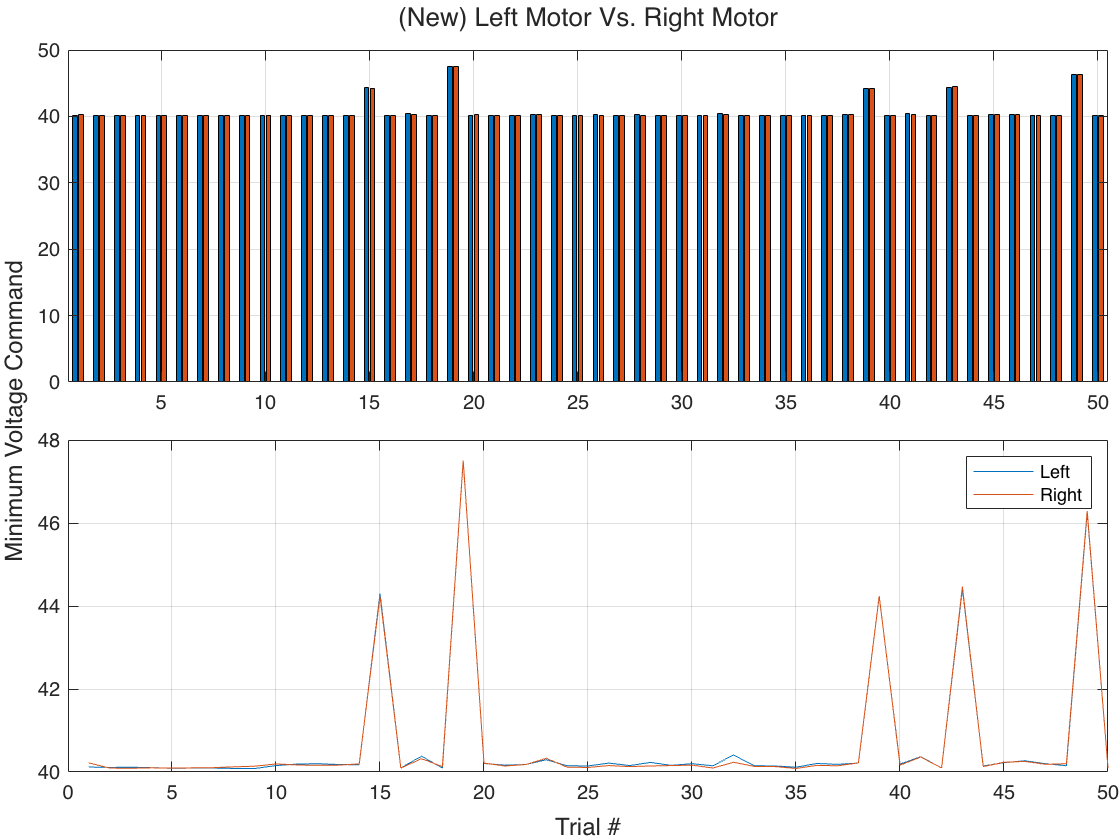

t = 1:1:j;
plots = tiledlayout(2,1,'TileSpacing','Compact','Padding','tight');
title(plots, '(New) Left Motor Vs. Right Motor');
ylabel(plots, 'Minimum Voltage Command');
xlabel(plots, 'Trial #')

nexttile;
bar([minL', minR'])
grid on;

nexttile;
plot(t,minL,t,minR)
grid on;

legend('Left','Right')

fprintf('Mean Left: %f \t Mean Right: %f\n',mean(minL),mean(minR))

Mean Left: 40.690022 	 Mean Right: 40.680322


fprintf('Std Left: %f \t Std Right: %f\n',std(minL),std(minR))

Std Left: 1.622884 	 Std Right: 1.628990


fprintf('Average Minimum Sum: %f', min(mean(minRsum),mean(minLsum)))

Average Minimum Sum: 81.360698

% mean(minL), mean(minR)
% std(minL), std(minR)